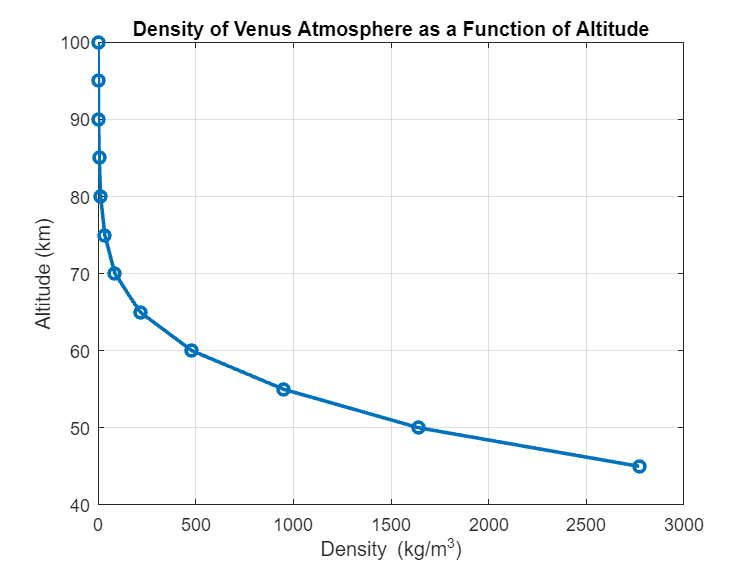

% Rene J. Holmes II
% ARO 4821L SP 24


% Constants
mass_payload = 3893.4; % Payload mass in kg
g_venus = 8.87; % Acceleration due to gravity on Venus in m/s^2
descent_speed = 0.5; % Desired descent speed in m/s
C_d = 1.5; % Assumed drag coefficient for parachute
R_CO2 = 8.314 / 44.01; % Specific gas constant for CO2 in J/(mol*K)

% Atmospheric data based on the Venusian atmosphere
% Assuming linear interpolation between the points for simplification
height_km = [45, 50, 55, 60, 65, 70, 75, 80, 85, 90, 95, 100];
temperature_C = [110, 75, 27, -10, -30, -43, -56, -76, -96, -104, -112, -112];
pressure_atm = [1.979, 1.066, 0.5314, 0.2357, 0.09765, 0.0369, 0.014, 0.00476, 0.0019, 0.000736, 0.000373, 0.0000266];

% Convert atmospheric pressure from atm to Pa and temperature from Celsius to Kelvin
pressure_Pa = pressure_atm * 101325; % Convert atm to Pascal
temperature_K = temperature_C + 273.15; % Convert Celsius to Kelvin

% Calculate density using the ideal gas law: p = rho * R * T
density_kg_m3 = pressure_Pa ./ (R_CO2 * temperature_K);

% Plot the density as a function of altitude
figure;
plot(density_kg_m3, height_km, 'o-', 'LineWidth', 2);
title('Density of Venus Atmosphere as a Function of Altitude');
xlabel('Density (kg/m^3)');
ylabel('Altitude (km)');
grid on;


% Calculate the gravitational force on the payload
F_g = mass_payload * g_venus; % Gravitational force in Newtons

% Use the density at 45 km for parachute area calculation
rho_45km = density_kg_m3(1); % Density in kg/m^3 at 45 km altitude

% Calculate the required parachute area (A) to achieve the desired descent speed
A = (2 * F_g) / (C_d * rho_45km * descent_speed^2);

% Assuming the parachute is a hemisphere (common for parachute shapes)
% Calculate the radius of a hemisphere with area A
r = sqrt(A / (2 * pi));

% Calculate the volume of the hemisphere (How much air is trapped beneath
% the parachute
V = (2/3) * pi * r^3;

% Display the calculated parachute area and volume
fprintf('The required parachute area is approximately %.2f square meters at an altitude of 45 km.\n', A);

The required parachute area is approximately 66.48 square meters at an altitude of 45 km.


fprintf('The corresponding volume of the inflated parachute (hemisphere) is approximately %.2f cubic meters.\n', V);

The corresponding volume of the inflated parachute (hemisphere) is approximately 72.09 cubic meters.
